# Modeling and Predicting The COVID-19 Pandemic Trajectory

-Samuel Zhang

The scope of this project is to mathematically model and analyze the growth and trajectory of COVID-19 pandemic using global data provided my John Hopkins Hospital. Since this is a Matlab Live Script Document, all the code and data are transparent and please feel free to criticize and leave your own suggestions. The data is up to data as of March 29, 2020. One can easily add and modify data regarding to one's needs using this livescript.

clc
clear
%%Plot Total Confirmed Cases
Country_Names=['Australia','China','Finland','Germany','Iran','Italy','Japan','SouthKorea','Malaysia','Singapore','United Kingdom','US']

Country_Names = 'AustraliaChinaFinlandGermanyIranItalyJapanSouthKoreaMalaysiaSingaporeUnited KingdomUS'

## Index Confirmed Cases from [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

This portion is the raw data provided by John Hopkins Hospital. The table is split using , and ; with , representing columns and ; representing rows. Rows: Confirmed Cases since Jan 22 2020, Columns: Countries in the order of `Country_Names.`

Confirmed_cases=[0,548,0,0,0,0,2,1,0,0,0,1;
0,643,0,0,0,0,2,1,0,1,2,1;
0,920,0,0,0,0,2,2,0,3,2,2;
0,1406,0,0,0,0,2,2,3,3,2,2;
4,2075,0,0,0,0,4,3,4,4,2,5;
5,2877,0,1,0,0,4,4,4,5,2,5;
5,5509,0,4,0,0,7,4,4,7,2,5;
6,6087,1,4,0,0,7,4,7,7,2,5;
9,8141,1,4,0,0,11,4,8,10,2,5;
9,9802,1,5,0,2,15,11,8,13,4,7;
12,11891,1,8,0,2,20,12,8,16,8,8;
12,16630,1,10,0,2,20,15,8,18,8,8;
12,19716,1,12,0,2,20,15,8,18,10,11;
13,23707,1,12,0,2,22,16,10,24,10,11;
13,27440,1,12,0,2,22,19,12,28,10,11;
14,30587,1,12,0,2,22,23,12,28,12,11;
15,34110,1,13,0,3,25,24,12,30,13,11;
15,36814,1,13,0,3,25,24,16,33,16,11;
15,39829,1,14,0,3,26,25,16,40,16,11;
15,42354,1,14,0,3,26,27,18,45,22,11;
15,44386,1,16,0,3,26,28,18,47,23,12;
15,44759,1,16,0,3,28,28,18,50,24,12;
15,59895,1,16,0,3,28,28,19,58,25,13;
15,66358,1,16,0,3,29,28,19,67,25,13;
15,68413,1,16,0,3,43,28,22,72,25,13;
15,70513,1,16,0,3,59,29,22,75,25,13;
15,72434,1,16,0,3,66,30,22,77,25,13;
15,74211,1,16,0,3,74,31,22,81,25,13;
15,74619,1,16,2,3,84,31,22,84,25,13;
15,75077,1,16,5,3,94,104,22,84,25,13;
15,75550,1,16,18,20,105,204,22,85,25,15;
15,77001,1,16,28,62,122,433,22,85,25,15;
15,77022,1,16,43,155,147,602,22,89,25,15;
15,77241,1,16,61,229,159,833,22,89,29,51;
15,77754,1,17,95,322,170,977,22,91,29,51;
15,78166,2,27,139,453,189,1261,22,93,29,57;
15,78600,2,46,245,655,214,1766,23,93,31,58;
15,78928,2,48,388,888,228,2337,23,93,36,60;
25,79356,3,79,593,1128,241,3150,25,102,39,68;
27,79932,6,130,978,1694,256,3736,29,106,52,74;
30,80136,6,159,1501,2036,274,4335,29,108,56,98;
39,80261,6,196,2336,2502,293,5186,36,110,67,118;
52,80386,6,262,2922,3089,331,5621,50,110,102,149;
55,80537,12,482,3513,3858,360,6088,50,117,136,217;
60,80690,15,670,4747,4636,420,6593,83,130,187,262;
63,80770,15,799,5823,5883,461,7041,93,138,241,402;
76,80823,23,1040,6566,7375,502,7314,99,150,320,518;
91,80860,30,1176,7161,9172,511,7478,117,150,371,583;
107,80887,40,1457,8042,10149,581,7513,129,160,441,959;
128,80921,59,1908,9000,12462,639,7755,149,178,527,1281;
128,80932,59,2078,10075,12462,639,7869,149,178,528,1663;
200,80945,155,3675,11364,17660,701,7979,197,200,880,2179;
250,80977,225,4585,12729,21157,773,8086,238,212,1238,2727;
297,81003,244,5795,13938,24747,839,8162,428,226,1254,3499;
377,81033,277,7272,14991,27980,839,8236,566,243,1681,4632;
452,81058,321,9257,16169,31506,878,8320,673,266,2137,6421;
568,81102,336,12327,17361,35713,889,8413,790,313,2861,7783;
681,81156,400,15320,18407,41035,924,8565,900,345,2991,13677;
791,81250,450,19848,19644,47021,963,8652,1030,385,4324,19100;
1071,81305,523,22213,20610,53578,1007,8799,1183,432,5437,25489;
1549,81435,626,24873,21638,59138,1101,8961,1306,455,6192,33276;
1682,81498,700,29056,23049,63927,1128,8961,1518,509,7206,43847;
2044,81591,792,32986,24811,69176,1193,9037,1624,558,8671,53740;
2364,81661,880,37323,27017,74386,1307,9137,1796,631,10226,65778;
2810,81782,958,43938,29406,80589,1387,9241,2031,683,12590,83836;
3143,81897,1041,50871,32332,86498,1468,9332,2161,732,15612,101657;
3640,81999,1167,57695,35408,92472,1693,9478,2320,802,18287,121478;
3984,82122,1240,62095,38309,97689,1866,9583,2470,844,20867,140886]

Confirmed_cases =            0         548           0           0           0           0           2           1           0           0           0           1
           0         643           0           0           0           0           2           1           0           1           2           1
           0         920           0           0           0           0           2           2           0           3           2           2
           0        1406           0           0           0           0           2           2           3           3           2           2
           4        2075           0           0           0           0           4           3           4           4           2           5
           5        2877           0           1           0           0           4           4           4           5           2           5
           5        5509           0           4           0           0           7           4           4    

## Calculate and Index Average Cases from [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19) with Microsoft Excel

This portion is the mean (average of 5 days) new cases data provided by John Hopkins Hospital and calculated via Microsoft Excel. The table is split using , and ; with , representing columns and ; representing rows. Rows: Average Growth of Confirmed Cases since Jan 22 2020, Columns: Countries in the order of `Country_Names.`

Rate_of_New_Cases=[0,0,0,0,0,0,0,0,0,0,0,0;
0,0,0,0,0,0,0,0,0,0,0,0;
0,0,0,0,0,0,0,0,0,0,0,0;
0,254.3333333,0,0,0,0,0,0.333333333,1,0.666666667,0,0.333333333;
1.333333333,385,0,0,0,0,0.666666667,0.333333333,1.333333333,0.333333333,0,1;
1.666666667,490.3333333,0,0.333333333,0,0,0.666666667,0.666666667,0.333333333,0.666666667,0,1;
0.333333333,1144.666667,0,1.333333333,0,0,1,0.333333333,0,1,0,0;
0.333333333,1070,0.333333333,1,0,0,1,0,1,0.666666667,0,0;
1.333333333,877.3333333,0.333333333,0,0,0,1.333333333,0,1.333333333,1,0,0;
1,1238.333333,0,0.333333333,0,0.666666667,2.666666667,2.333333333,0.333333333,2,0.666666667,0.666666667;
1,1250,0,1.333333333,0,0.666666667,3,2.666666667,0,2,2,1;
1,2276,0,1.666666667,0,0,1.666666667,1.333333333,0,1.666666667,1.333333333,0.333333333;
0,2608.333333,0,1.333333333,0,0,0,1,0,0.666666667,0.666666667,1;
0.333333333,2359,0,0.666666667,0,0,0.666666667,0.333333333,0.666666667,2,0.666666667,1;
0.333333333,2574.666667,0,0,0,0,0.666666667,1.333333333,1.333333333,3.333333333,0,0;
0.333333333,2293.333333,0,0,0,0,0,2.333333333,0.666666667,1.333333333,0.666666667,0;
0.666666667,2223.333333,0,0.333333333,0,0.333333333,1,1.666666667,0,0.666666667,1,0;
0.333333333,2075.666667,0,0.333333333,0,0.333333333,1,0.333333333,1.333333333,1.666666667,1.333333333,0;
0,1906.333333,0,0.333333333,0,0,0.333333333,0.333333333,1.333333333,3.333333333,1,0;
0,1846.666667,0,0.333333333,0,0,0.333333333,1,0.666666667,4,2,0;
0,1519,0,0.666666667,0,0,0,1,0.666666667,2.333333333,2.333333333,0.333333333;
0,801.6666667,0,0.666666667,0,0,0.666666667,0.333333333,0,1.666666667,0.666666667,0.333333333;
0,5169.666667,0,0,0,0,0.666666667,0,0.333333333,3.666666667,0.666666667,0.333333333;
0,7199.666667,0,0,0,0,0.333333333,0,0.333333333,5.666666667,0.333333333,0.333333333;
0,2839.333333,0,0,0,0,5,0,1,4.666666667,0,0;
0,1385,0,0,0,0,10,0.333333333,1,2.666666667,0,0;
0,1340.333333,0,0,0,0,7.666666667,0.666666667,0,1.666666667,0,0;
0,1232.666667,0,0,0,0,5,0.666666667,0,2,0,0;
0,728.3333333,0,0,0.666666667,0,6,0.333333333,0,2.333333333,0,0;
0,288.6666667,0,0,1.666666667,0,6.666666667,24.33333333,0,1,0,0;
0,310.3333333,0,0,5.333333333,5.666666667,7,57.66666667,0,0.333333333,0,0.666666667;
0,641.3333333,0,0,7.666666667,19.66666667,9.333333333,109.6666667,0,0.333333333,0,0.666666667;
0,490.6666667,0,0,8.333333333,45,14,132.6666667,0,1.333333333,0,0;
0,80,0,0,11,55.66666667,12.33333333,133.3333333,0,1.333333333,1.333333333,12;
0,244,0,0.333333333,17.33333333,55.66666667,7.666666667,125,0,0.666666667,1.333333333,12;
0,308.3333333,0.333333333,3.666666667,26,74.66666667,10,142.6666667,0,1.333333333,0,2;
0,282,0.333333333,9.666666667,50,111,14.66666667,263,0.333333333,0.666666667,0.666666667,2.333333333;
0,254,0,7,83,145,13,358.6666667,0.333333333,0,2.333333333,1;
3.333333333,252,0.333333333,11,116,157.6666667,9,461.3333333,0.666666667,3,2.666666667,3.333333333;
4,334.6666667,1.333333333,27.33333333,196.6666667,268.6666667,9.333333333,466.3333333,2,4.333333333,5.333333333,4.666666667;
1.666666667,260,1,26.66666667,302.6666667,302.6666667,11,395,1.333333333,2,5.666666667,10;
4,109.6666667,0,22,452.6666667,269.3333333,12.33333333,483.3333333,2.333333333,1.333333333,5,14.66666667;
7.333333333,83.33333333,0,34.33333333,473.6666667,351,19,428.6666667,7,0.666666667,15.33333333,17;
5.333333333,92,2,95.33333333,392.3333333,452,22.33333333,300.6666667,4.666666667,2.333333333,23,33;
2.666666667,101.3333333,3,136,608.3333333,515.6666667,29.66666667,324,11,6.666666667,28.33333333,37.66666667;
2.666666667,77.66666667,1,105.6666667,770,675,33.66666667,317.6666667,14.33333333,7,35,61.66666667;
5.333333333,44.33333333,2.666666667,123.3333333,606.3333333,913,27.33333333,240.3333333,5.333333333,6.666666667,44.33333333,85.33333333;
9.333333333,30,5,125.6666667,446,1096.333333,16.66666667,145.6666667,8,4,43.33333333,60.33333333;
10.33333333,21.33333333,5.666666667,139,492,924.6666667,26.33333333,66.33333333,10,3.333333333,40.33333333,147;
12.33333333,20.33333333,9.666666667,244,613,1096.666667,42.66666667,92.33333333,10.66666667,9.333333333,52,232.6666667;
7,15,6.333333333,207,677.6666667,771,19.33333333,118.6666667,6.666666667,6,29,234.6666667;
24,8,32,589,788,1732.666667,20.66666667,74.66666667,16,7.333333333,117.6666667,299.3333333;
40.66666667,15,55.33333333,835.6666667,884.6666667,2898.333333,44.66666667,72.33333333,29.66666667,11.33333333,236.6666667,354.6666667;
32.33333333,19.33333333,29.66666667,706.6666667,858,2362.333333,46,61,77,8.666666667,124.6666667,440;
42.33333333,18.66666667,17.33333333,895.6666667,754,2274.333333,22,50,109.3333333,10.33333333,147.6666667,635;
51.66666667,18.33333333,25.66666667,1154,743.6666667,2253,13,52.66666667,81.66666667,13.33333333,294.3333333,974;
63.66666667,23,19.66666667,1685,790,2577.666667,16.66666667,59,74.66666667,23.33333333,393.3333333,1050.333333;
76.33333333,32.66666667,26.33333333,2021,746,3176.333333,15.33333333,81.66666667,75.66666667,26.33333333,284.6666667,2418.666667;
74.33333333,49.33333333,38,2507,761,3769.333333,24.66666667,79.66666667,80,24,487.6666667,3772.333333;
130,49.66666667,41,2297.666667,734.3333333,4181,27.66666667,78,94.33333333,29,815.3333333,3937.333333;
252.6666667,61.66666667,58.66666667,1675,664.6666667,4039,46,103,92,23.33333333,622.6666667,4725.333333;
203.6666667,64.33333333,59,2281,813,3449.666667,40.33333333,54,111.6666667,25.66666667,589.6666667,6119.333333;
165,52,55.33333333,2704.333333,1057.666667,3346,30.66666667,25.33333333,106,34.33333333,826.3333333,6821.333333;
227.3333333,54.33333333,60,2755.666667,1322.666667,3486.333333,59.66666667,58.66666667,92.66666667,40.66666667,1006.666667,7310.333333;
255.3333333,63.66666667,55.33333333,3650.666667,1531.666667,3804.333333,64.66666667,68,135.6666667,41.66666667,1306.333333,10032;
259.6666667,78.66666667,53.66666667,4516,1771.666667,4037.333333,53.66666667,65,121.6666667,33.66666667,1795.333333,11959.66667;
276.6666667,72.33333333,69.66666667,4585.666667,2000.666667,3961,102,79,96.33333333,39.66666667,1899,12547.33333;
280.3333333,75,66.33333333,3741.333333,1992.333333,3730.333333,132.6666667,83.66666667,103,37.33333333,1751.666667,13076.33333]

Rate_of_New_Cases = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0254         0         0         0         0         0    0.0000    0.0001    0.0001         0    0.0000
    0.0001    0.0385         0         0         0         0    0.0001    0.0000    0.0001    0.0000         0    0.0001
    0.0002    0.0490         0    0.0000         0         0    0.0001    0.0001    0.0000    0.0001         0    0.0001
    0.0000    0.1145         0    0.0001         0         0    0.0001    0.0000         0    0.0001         0         0
    0.0000    0.1070    0.0000    0.0001         0         0    0.0001         0    0.0001    0.0001         0         0


## Index Total Confirmed Cases

The following table is the total confirmed cases since Jan 22, 2020. This is later used for modeling curve fit.

total_confirmed_cases=[555,656,943,1436,2120,2929,5580,6168,8236,9929,12044,16793,19889,23900,27643,30804,34401,37133,40163,42776,44817,45236,60384,66901,69046,71240,73274,75152,75655,76213,76835,78588,78974,79577,80422,81404,82762,84128,86027,88385,90322,92856,95136,97906,101824,105881,109867,113639,118677,125943,128421,145283,156195,167563,181704,197279,215040,242775,272345,304766,337400,378715,418552,468239,530369,594158,661681,721204]

total_confirmed_cases =          555         656         943        1436        2120        2929        5580        6168        8236        9929       12044       16793       19889       23900       27643       30804       34401       37133       40163       42776       44817       45236       60384       66901       69046       71240       73274       75152       75655       76213       76835       78588       78974       79577       80422       81404       82762       84128       86027       88385       90322       92856       95136       97906      101824      105881      109867      113639      118677      125943


## Plotting loglog Trajectory of The Selected Countries

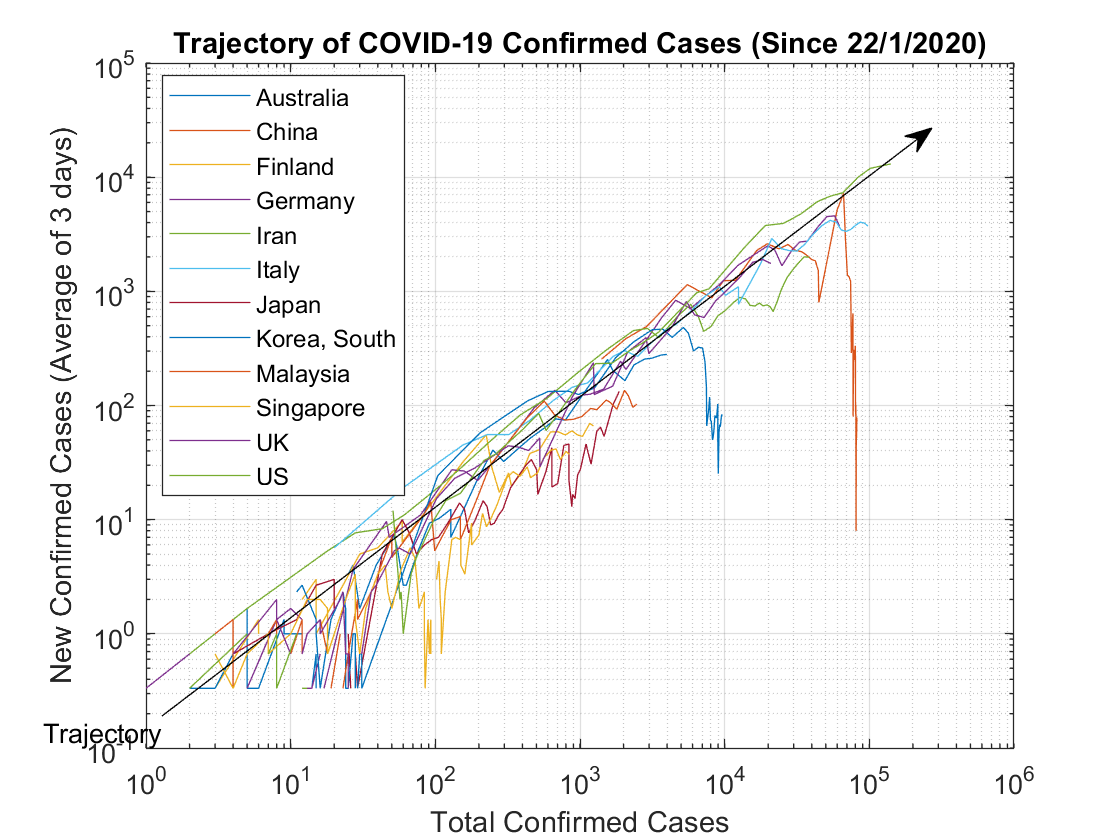

loglog (Confirmed_cases,Rate_of_New_Cases)
legend({'Australia','China','Finland','Germany','Iran','Italy','Japan','Korea, South','Malaysia','Singapore','UK','US'})
set(legend,...
    'Position',[0.144982988922427 0.409297035888904 0.216581636927913 0.501360560482978]);
% Create ylabel
ylabel({'New Confirmed Cases (Average of 3 days)'});

% Create xlabel
xlabel({'Total Confirmed Cases'});

% Create title
title({'Trajectory of COVID-19 Confirmed Cases (Since 22/1/2020)'});
grid on 
annotation('textarrow',[0.1446 0.8321],[0.1476 0.8476],'String','Trajectory')

In epidemiology and ecology, nothing in nature can sustain a perfect exponential growth. Population growth is often limited by a maximum capacity where lack of resources will limit the exponential growth and it eventually flatten out. In the case of COVID-19, the limiting factors that prevents it from growing forever are complex. Total available population for infection, healthcare system intervention, social distancing, wearing personal protective equipment that lowers R0 values are all significant impacts to the virus to follow a perfect natural growth trend. A more realistic mathematic model would be a sigmoid function, log function or many other functions that are better suited for population monitoring. However, it is very difficult to identify the future trend of growth amid the middle. Simply searching for derivatives is not enough in modeling disease like this. The following graph plots the New Confirmed Cases (5 days average) with total confirmed cases to see the position of growth each country is in where time is implied. The closer a country’s curve follows the black arrow, the closer to perfect exponential growth the country is. Any dropping off/deviation from the black arrow represents significant success in disease control, limiting perfect exponential growth. Note that this is a LogLog plot. 

## Plot of Total Confirmed Cases Since 22/1/2020

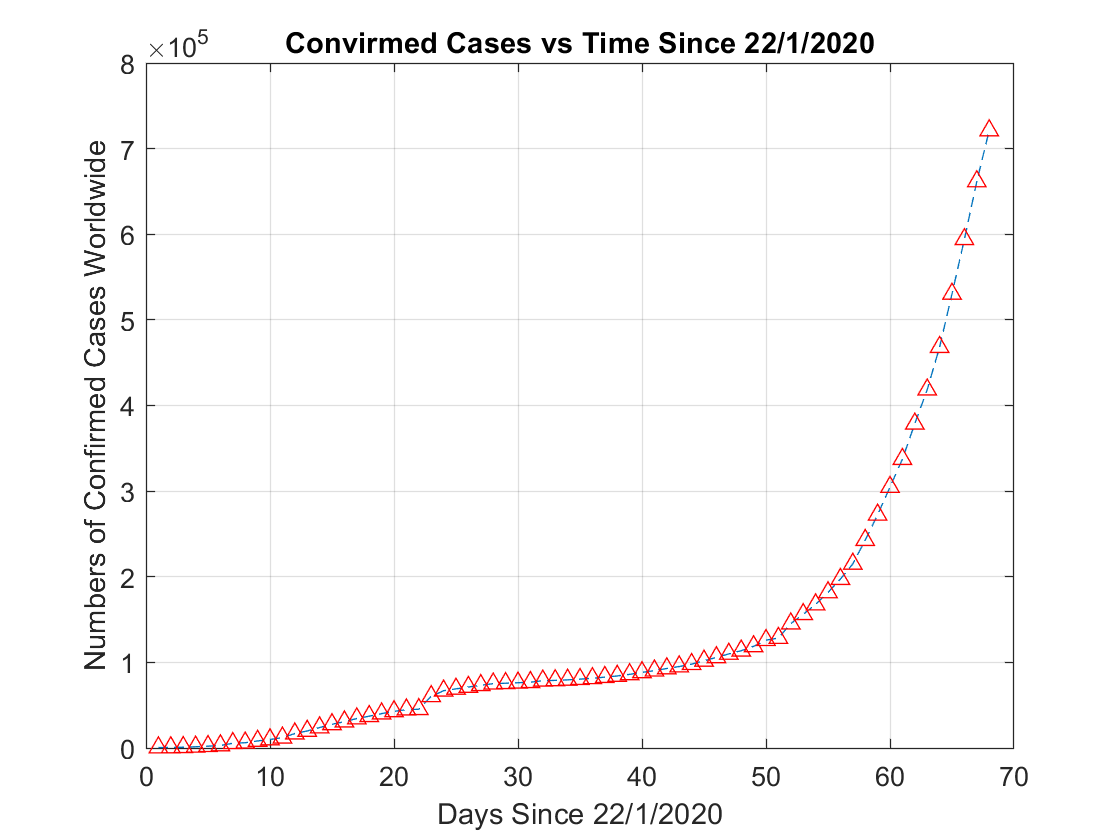

plot (total_confirmed_cases,'MarkerEdgeColor',[1 0 0],'Marker','^','LineStyle','--',...
    'Color',[0 0.447058826684952 0.74117648601532])
title('Convirmed Cases vs Time Since 22/1/2020')
xlabel('Days Since 22/1/2020')
ylabel('Numbers of Confirmed Cases Worldwide')

grid on

This is a standard Global Confirmed Cases VS Time plot. One can see that it is quite difficult to identify the future projection of the graph. Perhaps it is our silly sapien minds unable to understand the natural language of life and math. However, a simple curve fit could predict confirmed cases growth in the near future relatively accurately. 

## Plot of Total Confirmed Cases Since 22/1/2020 Curve Fit

%% Fit: 'Confirmed Cases of COVID-19 Since 22/1/2020 Fit'.
[xData, yData] = prepareCurveData( [], total_confirmed_cases );

% Set up fittype and options.
ft = fittype( 'exp1' );
excludedPoints = excludedata( xData, yData, 'Indices', [16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [8394.59673873853 0.0601158198762684];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Create a figure for the plots.
figure( 'Name', 'Confirmed Cases of COVID-19 Since 22/1/2020 Fit' );

% Plot fit with data.
subplot( 2, 1, 1 );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'total_confirmed_cases', 'Excluded total_confirmed_cases', 'Confirmed Cases of COVID-19 Since 22/1/2020 Fit', 'Location', 'NorthEast' );
% Label axes
ylabel total_confirmed_cases
grid on

% Plot residuals.
subplot( 2, 1, 2 );
h = plot( fitresult, xData, yData, excludedPoints, 'residuals' );
legend( h, 'Confirmed Cases of COVID-19 Since 22/1/2020 Fit - residuals', 'Excluded total_confirmed_cases', 'Zero Line', 'Location', 'NorthEast' );
% Label axes
ylabel total_confirmed_cases
grid on

subplot(2,1,1)
legend({'Confirmed Cases','Excluded Confirmed Cases','Confirmed Cases of COVID-19 Since 22/1/2020 Fit'},'Location','northeast')
title('Confirmed Cases of COVID-19 Since 22/1/2020 Fit')
xlabel('Days Since 22/1/2020')
ylabel('Total Confirmed Cases')
subplot(2,1,2)
legend({'Confirmed Cases of COVID-19 Since 22/1/2020 Fit - residuals','Excluded Confirmed Cases','Zero Line'},'Location','northeast')
title('Residuals Plot')
xlabel('Days Since 22/1/2020')
ylabel('Total Confirmed Cases')

Before using the curve fit data to extrapolate information, please note that this plot makes many assumptions, disregards possibility of the growth ever decreasing, trusts the data provided is 100% accurate and gathers all the cases (so unlikely it is impossible), and most importantly ignores any possible future efforts that could be done via governments to slow down infection. Please use this graph and its curve vit results with a grain of salt and in conjunction with the first plot. Green datapoints are excluded for a better fit (yeah yeah i know messing with data to fit my function -_-). The residual plot shows how much do the data points deviate from the curve fit function.

## Fit model to data.

[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model Exp1:
     fitresult(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       627.4  (486.9, 768)
       b =      0.1036  (0.1001, 0.1071)

gof = struct with fields:
           sse: 5.1316e+09
       rsquare: 0.9966
           dfe: 35
    adjrsquare: 0.9965
          rmse: 1.2109e+04


format short

Here is your function in the form of ${a\cdot e}^{b\cdot x}$, enjoy! Stay safe!